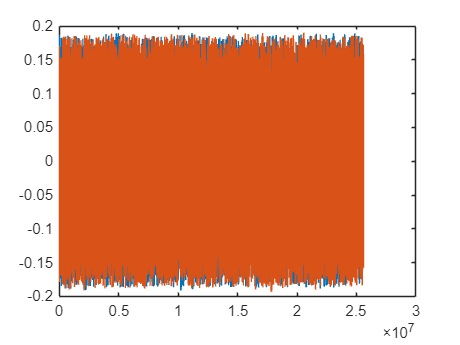

clc;
clear;
fs=125e6;
fc=20e6;
Rb=5e6;
sps=fs/Rb;

M=4;


symbolnumber=1024;
databit=randi([0 1],symbolnumber*log2(M),1);
modsymbol=pskmod(databit,4,pi/4,"gray","InputType","bit");

%RRC滤波器
Txrrc=comm.RaisedCosineTransmitFilter(FilterSpanInSymbols=12,RolloffFactor=0.35,OutputSamplesPerSymbol=sps,...
  Shape="Square root" );

a=readmatrix("C:\Users\Administrator\Desktop\共享文件夹\2.csv");
 
 modsymbol=a(:,1)+1i*a(:,2);

txbaseband=Txrrc(modsymbol);
plot([real(txbaseband),imag(txbaseband)]);

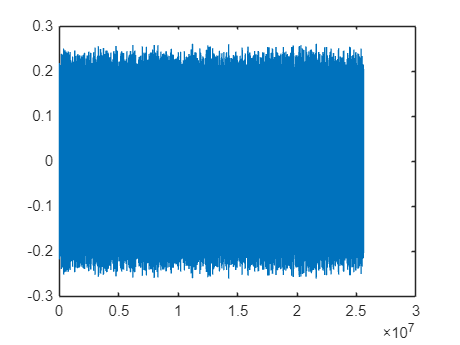


t=(0:length(txbaseband)-1)/fs;
carrier=exp(1i*2*pi*fc*t).';
RFSignal=real(txbaseband.*carrier);
plot(RFSignal);

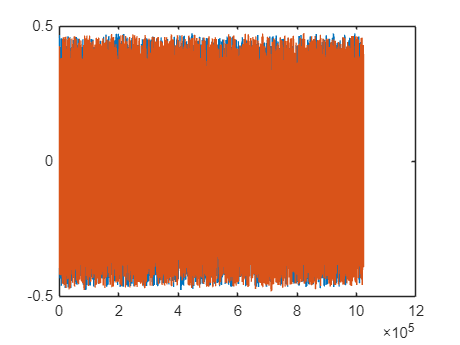

%接收
%下变频
carrier=exp(-1i*2*pi*fc*t).';
RFreceive=RFSignal.*carrier;
%匹配滤波
Rxrrc=comm.RaisedCosineReceiveFilter(DecimationFactor=25,DecimationOffset=0,FilterSpanInSymbols=12,RolloffFactor=0.35, ...
    Shape="Square root",InputSamplesPerSymbol=sps);
rxbaseband=Rxrrc(RFreceive);
plot([real(rxbaseband),imag(rxbaseband)]);

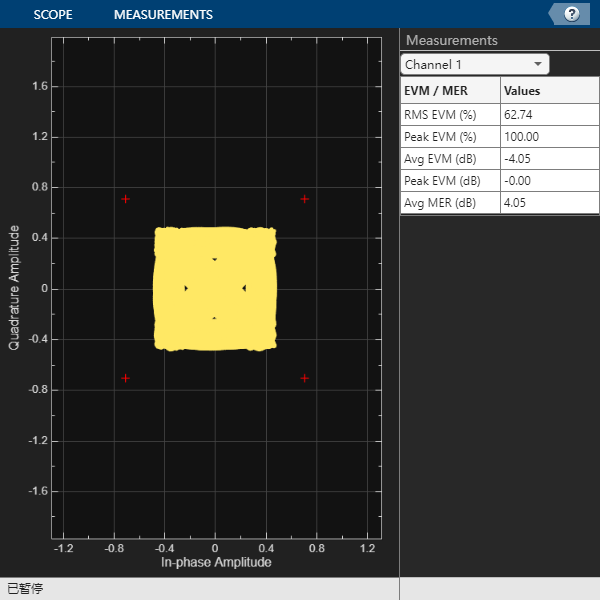

datademod=pskdemod(rxbaseband,4,pi/4,"gray","OutputType","bit");


 Reference=pskmod(0:3, 4, pi/4);
 ConstellationDiagram= comm.ConstellationDiagram(ShowReferenceConstellation=true, ...
                    EnableMeasurements=true,...
                    MeasurementInterval='Current display',...
                    ReferenceConstellation=Reference,...
                    EVMNormalization='Average constellation power');
 rxDecimated=rxbaseband;
 rxDecimated=rxDecimated(1:end);
         ConstellationDiagram(rxDecimated);